This function creates a filter that can be applied on a signal to compensate for chromatic dispersion

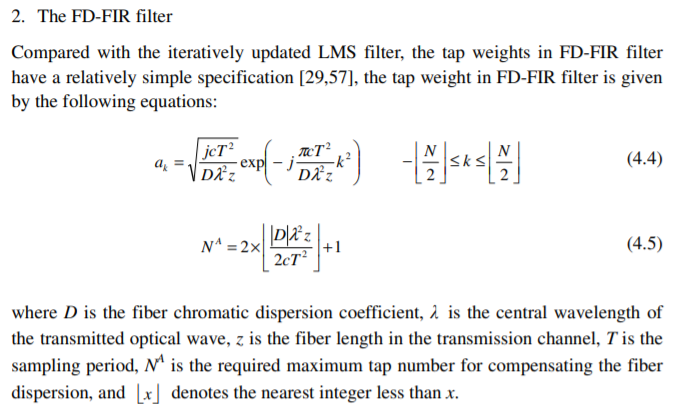

Requires chromatic dispersion coefficient D, wavelength $\lambda$, fiber length z, sampling period T, and max tap number N.

//Hard coded values for simplicity: D, z, $\lambda
$ where D = 16ps/nm/km (typically for optical comms), z = 5000km, $\lambda$ = 1550nm//

function CD_FD_FIR = CD_Filter(symbol_rate,D,z,l)

%D = 17*10^(-6); %s/m/m
%z = 40e3;
lambda = l; %1550*10^(-9);

c = 3e8; % m/s

beta_2 = -lambda*lambda*D/(2*pi*c);

        
downscaled_time_step = 1/symbol_rate/2;
rho = 2*pi*abs(beta_2)*z/(downscaled_time_step^2);
%K= abs(beta_2)*distance/2/(downscaled_time_step^2);
%N=2*floor(2*pi*K)+1;
%nv=[-(N-1)/2:(N-1)/2];
m = floor(rho/2);
kv = [-m:m];
CD_FD_FIR = (1/sqrt(rho))*exp((1i*pi/(rho))*kv.^2);

end

function CD_FIR = Lectures(sample_rate,D,z,l)

%% D = -(2πc/λ^2)β2 => -(Dλ^2)/(2πc) = β2


%Ignoring the sign change since we find absolute value regardless

c = 299792458; % m/s

beta_2 = (D*l^2)/(2*pi*c);

T = 1/sample_rate;

M = floor(pi*beta_2*z/(T^2));

k = (-M:M);


if M == 0
    k = 1;
    M = 1;
end

%CD_FIR = ifftshift(ifft(exp(1j*ifftshift(k).^2/(M*2/pi))));
CD_FIR = 1/sqrt(2*M)*exp(-1j*pi*(k.^2)/(2*M));

end